# **Circuitos Electricos II**

**Roberto Sanchez Figueroa    **

**brrsanchezfi@unal.edu.co**

# **Soluciones propuestas para los ejercicios del taller 9**

## Problema 1 

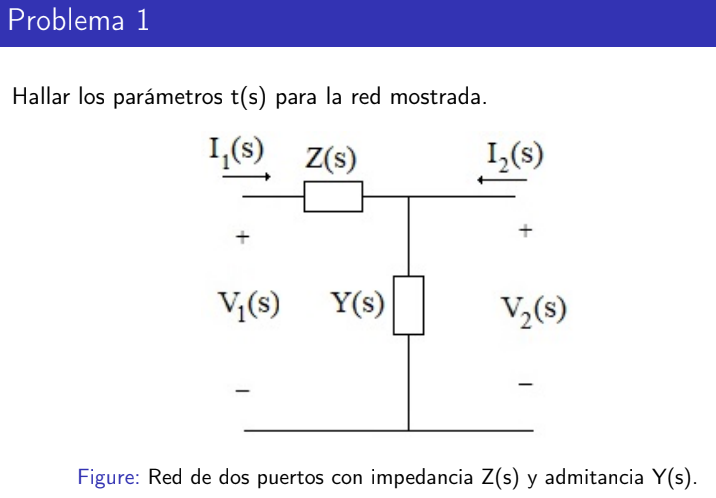

### Manera 1

apartir de la matriz de impedancia hallar la matriz de transmision T


$$Z_{11} =Z\left(s\right)+\frac{1}{\left(Y\left(s\right)\right)}$$



$$Z_{21} =\frac{1}{Y\left(s\right)}$$



$$Z_{22} =\frac{1}{Y\left(s\right)}$$



$$Z_{12} =\frac{1}{Y\left(s\right)}$$


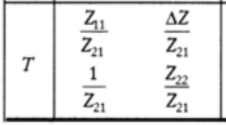

syms Y Z

%matriz de impedancia

z = [(Z+(1/Y)) 1/Y;
    1/Y 1/Y]

$$z = \left(\begin{array}{cc} Z+\frac{1}{Y} & \frac{1}{Y}\\ \frac{1}{Y} & \frac{1}{Y} \end{array}\right)$$


%calculamos el determinante

det_z = det(z);

%calculo de t_s apartir de los valores de la
%matriz de impedancia

t_s = simplify([z(1,1)/z(1,2)  det_z/z(2,1);
       1/z(2,1) z(2,2)/z(2,1)])

$$t\_s = \left(\begin{array}{cc} Y\,Z+1 & Z\\ Y & 1 \end{array}\right)$$

### Manera 2

Usar la manera convencional

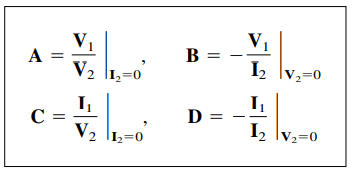

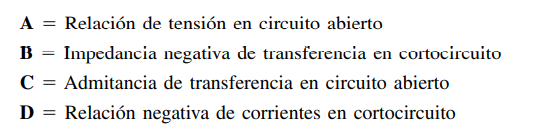

**A = Relacion de tension en circuito abiero**

Divisor de tension


$$A=\frac{\frac{1}{Y\left(s\right)}}{\frac{1}{Y\left(s\right)}+Z\left(s\right)}\;$$


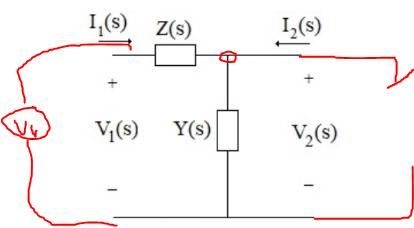

**B = Impedancia negativa de transferencia en cortocircuito**


$$B=-\frac{V_1 }{I_2 }=-\frac{I_1 \left(Z\left(s\right)\right)}{I_2 }$$
  
$$I_{1=} \;{-I}_2$$


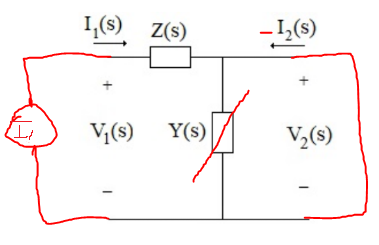

**C = Admitancia de transferencia en circuito abierto**

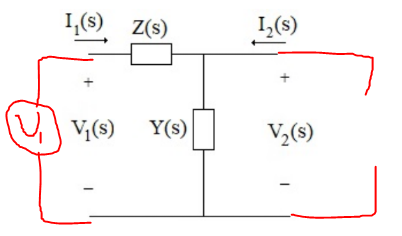


$$C=\frac{I_1 }{V_2 }=\frac{\frac{V_1 }{Z\left(s\right)+\frac{1}{Y\left(s\right)}}}{V_1 \frac{\frac{1}{Y\left(s\right)}}{Z\left(s\right)+\frac{1}{Y\left(s\right)}}}=Y\left(s\right)\;$$


**D = Relacion negativa de corrientes en cortocircuito **

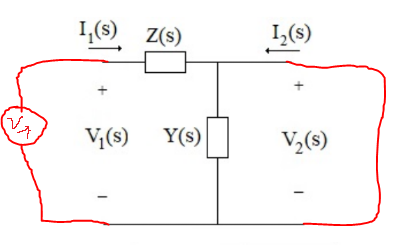


$$D=-\frac{I_1 }{I_2 }=-\frac{V_1 Z\left(s\right)}{{-V}_1 Z\left(s\right)}=1$$



$$T=\;\left(\begin{array}{cc}
Y\,Z+1 & Z\\
Y & 1
\end{array}\right)$$


## Problema 2

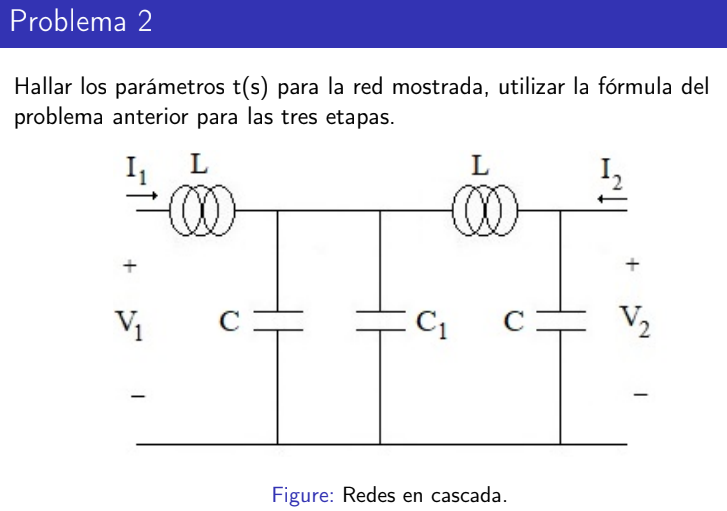

### Metodo 1

Acople en cascada apartir de la solucion del primer punto

c = 2;
c_1 = 3;
l = 2;

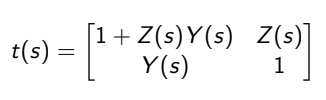

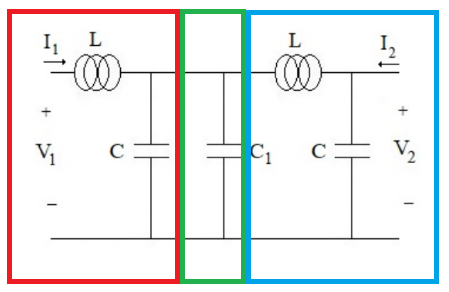


$$T_{\textrm{Rojo}} =\left(\begin{array}{cc}
{\textrm{LCs}}^2 +1 & \textrm{Ls}\\
\textrm{Cs} & 1
\end{array}\right)\;$$



$$Z_{\textrm{verde}} =\left(\begin{array}{cc}
\frac{1}{\textrm{Cs}} & \frac{1}{\textrm{Cs}}\\
\frac{1}{\textrm{Cs}} & \frac{1}{\textrm{Cs}}
\end{array}\right)\Rightarrow T_{\textrm{verde}} =\left(\begin{array}{cc}
1 & 0\\
\textrm{Cs} & 1
\end{array}\right)\;$$



$$T_{\textrm{Azul}} =\left(\begin{array}{cc}
{\textrm{LCs}}^2 +1 & \textrm{Ls}\\
\textrm{Cs} & 1
\end{array}\right)$$


syms C L C_1 s

t_rojo = [(L*C*s^2)+1 L*s;
           C*s 1]

$$t\_rojo = \left(\begin{array}{cc} C\,L\,s^{2}+1 & L\,s\\ C\,s & 1 \end{array}\right)$$

t_verde = [1 0;
           (C_1*s) 1] 

$$t\_verde = \left(\begin{array}{cc} 1 & 0\\ C_{1}\,s & 1 \end{array}\right)$$


t_azul = [(L*C*s^2)+1 L*s;
           C*s 1]

$$t\_azul = \left(\begin{array}{cc} C\,L\,s^{2}+1 & L\,s\\ C\,s & 1 \end{array}\right)$$

t_total = simplify(t_rojo * t_verde * t_azul)

$$t\_total = \begin{array}{l} \left(\begin{array}{cc} \left(\sigma_{1}+1\right)\,\left(\sigma_{1}+C_{1}\,L\,s^{2}+1\right)+\sigma_{1} & L\,s\,\left(\sigma_{1}+C_{1}\,L\,s^{2}+2\right)\\ \left(\sigma_{1}+1\right)\,\left(C\,s+C_{1}\,s\right)+C\,s & L\,s\,\left(C\,s+C_{1}\,s\right)+1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=C\,L\,s^{2} \end{array}$$

t_total = simplify(subs(t_total,[C_1 C L],[c_1 c l]))

$$t\_total = \left(\begin{array}{cc} 40\,s^{4}+18\,s^{2}+1 & 20\,s^{3}+4\,s\\ s\,\left(20\,s^{2}+7\right) & 10\,s^{2}+1 \end{array}\right)$$

### Metodo 2

Apartir de la matriz impedancia del sistema hallar los parametros

syms V_1 V_2 I_1 I_2 L C C_1 s

syms V_1 V_2 I_1 I_2 L C C_1 s

% Apartir de impedancias

Z_11 = ((C*L*s^2 + 1)*(C*L*s^2 + C_1*L*s^2 + 1) + C*L*s^2)/((C*L*s^2 + 1)*(C*s + C_1*s) + C*s);
Z_21 = 1/((C*L*s^2 + 1)*(C*s + C_1*s) + C*s);
Z_22 = 1/((C*L*s^2 + 1)*(C*s + C_1*s) + C*s);
Z_12 = (L*s*(C*s + C_1*s) + 1)/((C*L*s^2 + 1)*(C*s + C_1*s) + C*s);

Z=[Z_11 Z_21; Z_22 Z_12]

$$Z = \begin{array}{l} \left(\begin{array}{cc} \frac{\left(C\,L\,s^{2}+1\right)\,\left(C\,L\,s^{2}+C_{1}\,L\,s^{2}+1\right)+C\,L\,s^{2}}{\sigma_{1}} & \frac{1}{\sigma_{1}}\\ \frac{1}{\sigma_{1}} & \frac{L\,s\,\left(C\,s+C_{1}\,s\right)+1}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\left(C\,L\,s^{2}+1\right)\,\left(C\,s+C_{1}\,s\right)+C\,s \end{array}$$



det_Z = det(Z);

%calculo de t_s apartir de los valores de la
%matriz de impedancia

t_s = ([Z(1,1)/Z(2,1) det_Z/Z(2,1);
       1/Z(2,1) Z(2,2)/Z(2,1)]);

t_total = simplify(subs(t_s,[C_1 C L],[c_1 c l]))

$$t\_total = \left(\begin{array}{cc} 40\,s^{4}+18\,s^{2}+1 & 20\,s^{3}+4\,s\\ s\,\left(20\,s^{2}+7\right) & 10\,s^{2}+1 \end{array}\right)$$

## Problema 3

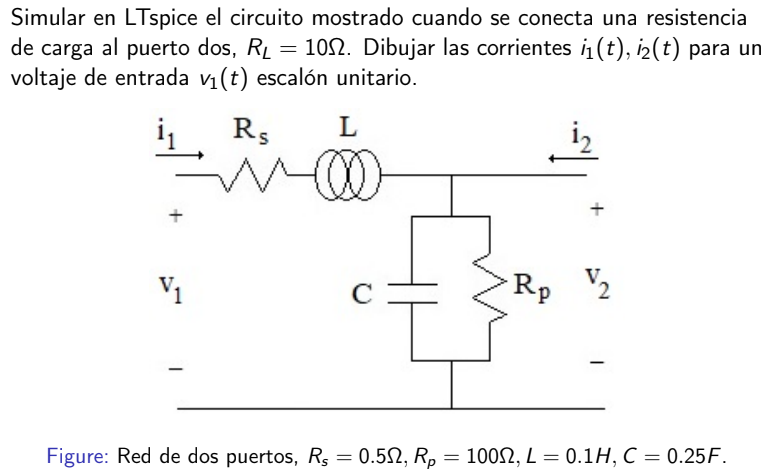

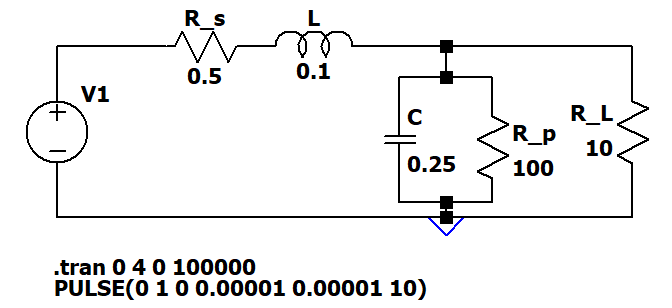

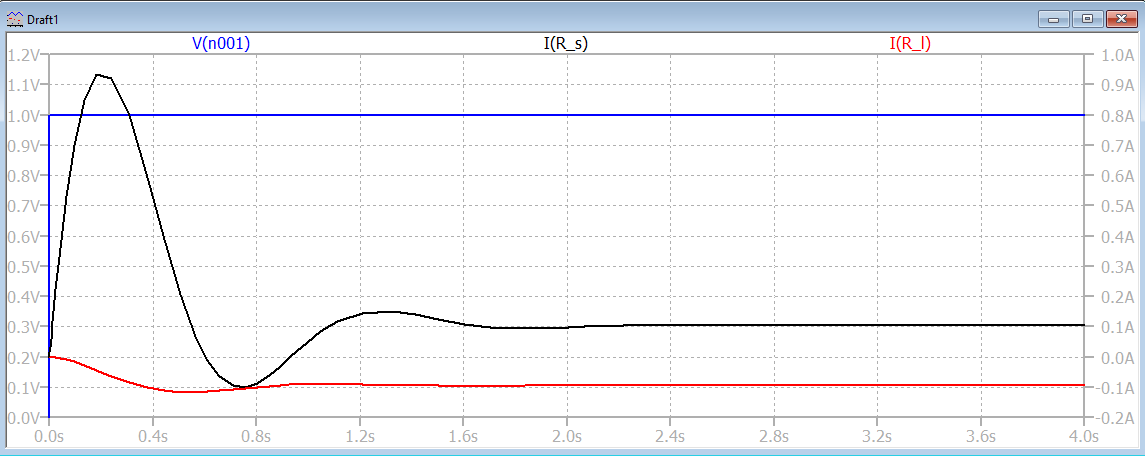

function x = paralelo(n1,n2)

    x = (n1*n2)/(n1+n2);

end